% Universidad Europea Internacional
% Asignatura: Navegación Autónoma de Robots
% Proyecto Integrador (I) - Localización

## Proyecto Integrador I . Localización de Robots

Configuración

clear; close all; clc;

% Configuración
% Vamos a adicionar al path las carpetas donde se encuentran los archivos 
% que tienen las diferentes funciones (src)

addpath('src');

% Luego asignamos el nombre del archivo de datos rosbag a una variable y
% validamos si existe
bagFile = 'mir_basics_20251210_114529.bag';

if ~exist(bagFile, 'file')
    error('No se encuentra el archivo rosbag: %s', bagFile);
end

% Crear directorio de resultados si no existe
if ~exist('resultados', 'dir')
    mkdir('resultados');
end

fprintf('Hemos realizado la configuración\n');

Hemos realizado la configuración


Ahora iniciamos el análisi exploratorio

Cargando rosbag: mir_basics_20251210_114529.bag

Topics disponibles:
    {'/amcl_pose'             }
    {'/base_pose_ground_truth'}
    {'/clock'                 }
    {'/cmd_vel'               }
    {'/imu_data'              }
    {'/joint_states'          }
    {'/map'                   }
    {'/map_metadata'          }
    {'/mir/joint_states'      }
    {'/move_base_simple/goal' }
    {'/odom'                  }
    {'/odometry/filtered'     }
    {'/particlecloud'         }
    {'/scan'                  }
    {'/tf'                    }
    {'/tf_static'             }

Leídos 16636 mensajes de /odom
Leídos 20191 mensajes de /base_pose_ground_truth
Leídos 1397 mensajes de /amcl_pose


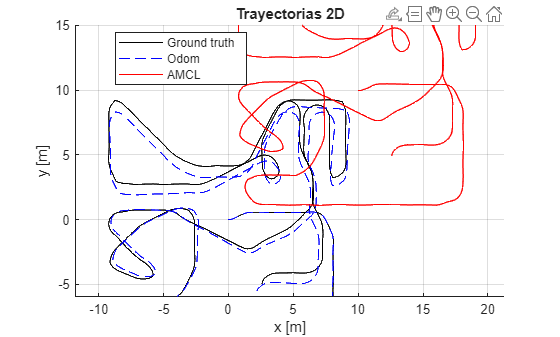

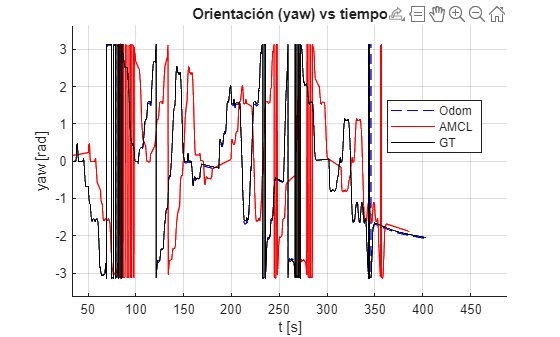


Listo. Revisa las figuras generadas.


analyze_bag(bagFile);

Scan 1 de 10003
RangeMin = 0.050, RangeMax = 29.000


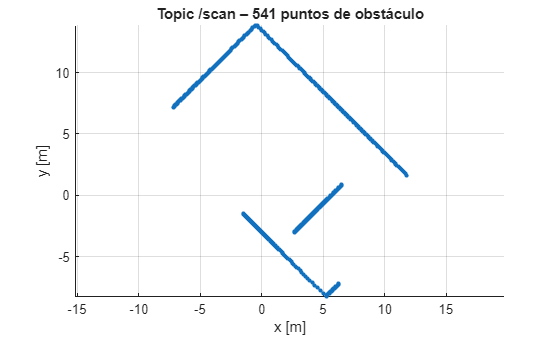

pause(2);

% Visualizamos el scan láser
plot_scan(bagFile);

pause(2);

fprintf('Se ha finalizado el Análisis exploratorio\n\n');

Se ha finalizado el Análisis exploratorio



Ahora Vamos a establecer la configuración para el EKF, UKF y MCL

fprintf('Configuración de parámetros\n');

Configuración de parámetros


fprintf('---------------------------------------\n');

---------------------------------------



% Establecemos los Parámetros iniciales para EKF
params_ekf = struct();
params_ekf.Q = diag([0.01, 0.01, 0.005].^2);  % Ruido del proceso
params_ekf.R = diag([0.2, 0.2].^2);           % Ruido de medición
params_ekf.x0 = [0; 0; 0];                    % Estado inicial
params_ekf.P0 = diag([0.1, 0.1, 0.05].^2);    % Covarianza inicial
params_ekf.max_innovation = 0.5;              % Límite de innovación

% Ahora visualizamos los parámetros establecidos para EKF
fprintf('Parámetros EKF:\n');

Parámetros EKF:


fprintf('  Q (proceso): diag([0.01, 0.01, 0.005]²)\n');

  Q (proceso): diag([0.01, 0.01, 0.005]²)


fprintf('  R (medición): diag([0.2, 0.2]²)\n');

  R (medición): diag([0.2, 0.2]²)


fprintf('  x0: [0, 0, 0]\n');

  x0: [0, 0, 0]



% Establecemos los Parámetros iniciales para UKF
params_ukf = struct();
params_ukf.Q = diag([0.01, 0.01, 0.005].^2);    % Ruido del proceso
params_ukf.R = diag([0.2, 0.2].^2);             % Ruido de medición
params_ukf.x0 = [0; 0; 0];                      % Estado inicial
params_ukf.P0 = diag([0.1, 0.1, 0.05].^2);      % Covarianza inicial
params_ukf.alpha = 0.001;                       % Parámetro de dispersión
params_ukf.beta = 2;                            % Óptimo para Gaussianas
params_ukf.kappa = 0;                           % Escalado secundario
params_ukf.max_innovation = 0.5;

fprintf('\nParámetros UKF:\n');


Parámetros UKF:


fprintf('  Q (proceso): diag([0.01, 0.01, 0.005]²)\n');

  Q (proceso): diag([0.01, 0.01, 0.005]²)


fprintf('  R (medición): diag([0.2, 0.2]²)\n');

  R (medición): diag([0.2, 0.2]²)


fprintf('  Alpha: %.4f, Beta: %.1f, Kappa: %.1f\n', ...
        params_ukf.alpha, params_ukf.beta, params_ukf.kappa);

  Alpha: 0.0010, Beta: 2.0, Kappa: 0.0



% Establecemos los Parámetros iniciales para MCL
params_mcl = struct();
params_mcl.n_particles = 1000;
params_mcl.map_size = [-10 10 -10 10];
params_mcl.alpha = [0.01, 0.01, 0.02, 0.01];   % Ruido de odometría
params_mcl.sensor_std = 0.5;
params_mcl.resample_threshold = 0.5;

fprintf('\nParámetros MCL:\n');


Parámetros MCL:


fprintf('  Partículas: %d\n', params_mcl.n_particles);

  Partículas: 1000


fprintf('  Alpha (ruido): [0.2, 0.2, 0.1, 0.1]\n');

  Alpha (ruido): [0.2, 0.2, 0.1, 0.1]


fprintf('  Sensor std: %.2f m\n', params_mcl.sensor_std);

  Sensor std: 0.50 m


Una vez configurados los parámetros vamos a ejecutar los algoritmos y hacer la evaluación

fprintf('Iniciamos la evaluación\n');

Iniciamos la evaluación


fprintf('---------------------------------------\n');

---------------------------------------


% Evaluamos el EKF
fprintf('>>> Evaluando EKF...\n');

>>> Evaluando EKF...


metrics_ekf = evaluate_localization(bagFile, 'ekf', params_ekf);

=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: EKF
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
=== Iniciando EKF Localization ===
Cargando rosbag: mir_basics_20251210_114529.bag
Leyendo 16636 mensajes de odometría...
Leyendo 10003 mensajes de láser...

Ejecutando filtro EKF...
Progreso: 10% 20% 30% 40% 50% 60% 70% 80% 90% 100% 
✓ EKF completado
Estados estimados: 16636
Covarianza final: trace = 0.0125
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---
RMSE posición:    0.7085 m
RMSE orientación: 0.0854 rad (4.89°)
MAE posición:     0.5845 m
MAE orientación:  0.0364 rad (2.09°)
Error máx posición: 1.1660 m
Desv. std posición: 0.4005 m

Incertidumbre media: 0.0072

--- COMPARACIÓN CON ODOMETRÍA ---
RMSE odometría: 0.5749 m
Mejora:         -23.2%

=== EVALUACIÓN COMPLETADA ===



fprintf('\n');

% Evaluar UKF
fprintf('>>> Evaluando UKF...\n');

>>> Evaluando UKF...


metrics_ukf = evaluate_localization(bagFile, 'ukf', params_ukf);

=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: UKF
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
=== Iniciando UKF Localization ===
Cargando rosbag: mir_basics_20251210_114529.bag
Leyendo 16636 mensajes de odometría...
Leyendo 10003 mensajes de láser...

Ejecutando filtro UKF...
Parámetros: alpha=0.0010, beta=2.0, kappa=0.0
Progreso: 10% 20% 30% 40% 50% 60% 70% 80% 90% 100% 
✓ UKF completado
Estados estimados: 16636
Covarianza final: trace = 0.0125
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---
RMSE posición:    0.5942 m
RMSE orientación: 0.0670 rad (3.84°)
MAE posición:     0.4929 m
MAE orientación:  0.0249 rad (1.43°)
Error máx posición: 1.0376 m
Desv. std posición: 0.3318 m

Incertidumbre media: 0.0072

--- COMPARACIÓN CON ODOMETRÍA ---
RMSE odometría: 0.5749 m
Mejora:         -3.4%

=== EVALUACIÓN COMPLETADA ===



fprintf('\n');

% Evaluar MCL
fprintf('>>> Evaluando MCL...\n');

>>> Evaluando MCL...


metrics_mcl = evaluate_localization(bagFile, 'mcl', params_mcl);

=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: MCL
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
=== Iniciando MCL (Monte Carlo Localization) ===
Cargando rosbag: mir_basics_20251210_114529.bag
Leyendo 16636 mensajes de odometría...
Leyendo 10003 mensajes de láser...

Ejecutando filtro MCL...
Partículas: 1000
Progreso: 10% 20% 30% 40% 50% 60% 70% 80% 90% 100% 
✓ MCL completado
Estados estimados: 16636
N_eff promedio: 800.0 / 1000
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---
RMSE posición:    0.5902 m
RMSE orientación: 0.3053 rad (17.49°)
MAE posición:     0.4945 m
MAE orientación:  0.2834 rad (16.24°)
Error máx posición: 0.9805 m
Desv. std posición: 0.3223 m
N_eff promedio: 800.0

--- COMPARACIÓN CON ODOMETRÍA ---
RMSE odometría: 0.5749 m
Mejora:         -2.7%

=== EVALUACIÓN COMPLETADA ===



fprintf('\n');

% Evaluar odometría (baseline)
fprintf('>>> Evaluando Odometría (baseline)...\n');

>>> Evaluando Odometría (baseline)...


metrics_odom = evaluate_localization(bagFile, 'odom');

=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: ODOM
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---
RMSE posición:    0.5749 m
RMSE orientación: 0.0646 rad (3.70°)
MAE posición:     0.4753 m
MAE orientación:  0.0286 rad (1.64°)
Error máx posición: 0.9731 m
Desv. std posición: 0.3233 m

--- COMPARACIÓN CON ODOMETRÍA ---
RMSE odometría: 0.5749 m
Mejora:         0.0%

=== EVALUACIÓN COMPLETADA ===



fprintf('\n');

% Evaluar AMCL (si está disponible)
try
    fprintf('>>> Evaluando AMCL...\n');
    metrics_amcl = evaluate_localization(bagFile, 'amcl');
    fprintf('\n');
    has_amcl = true;
catch ME
    warning('AMCL no disponible en el bag: %s', bagFile);
    has_amcl = false;
end

>>> Evaluando AMCL...


=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: AMCL
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---



fprintf('Se han completado las evaluaciones\n');

Se han completado las evaluaciones


fprintf('---------------------------------------\n');

---------------------------------------


Iniciamos la visualización de las gráficas


% Opciones de guardado
vis_options = struct();
vis_options.save_figures = true;
vis_options.output_dir = 'resultados';
vis_options.format = 'png';
vis_options.show_particles = true;

% Visualizar EKF
fprintf('Generando gráficas de EKF...\n');

Generando gráficas de EKF...


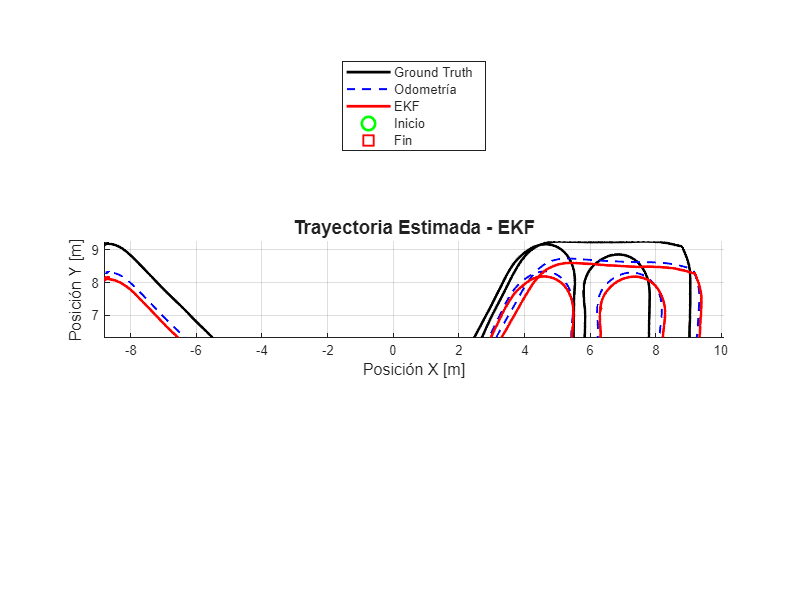

✓ Guardado: trayectoria_ekf.png


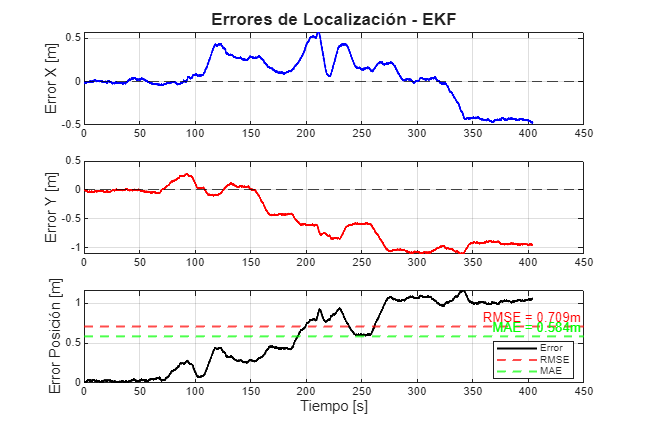

✓ Guardado: error_posicion_ekf.png


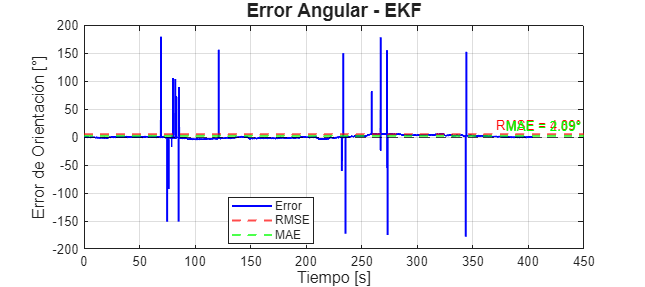

✓ Guardado: error_orientacion_ekf.png


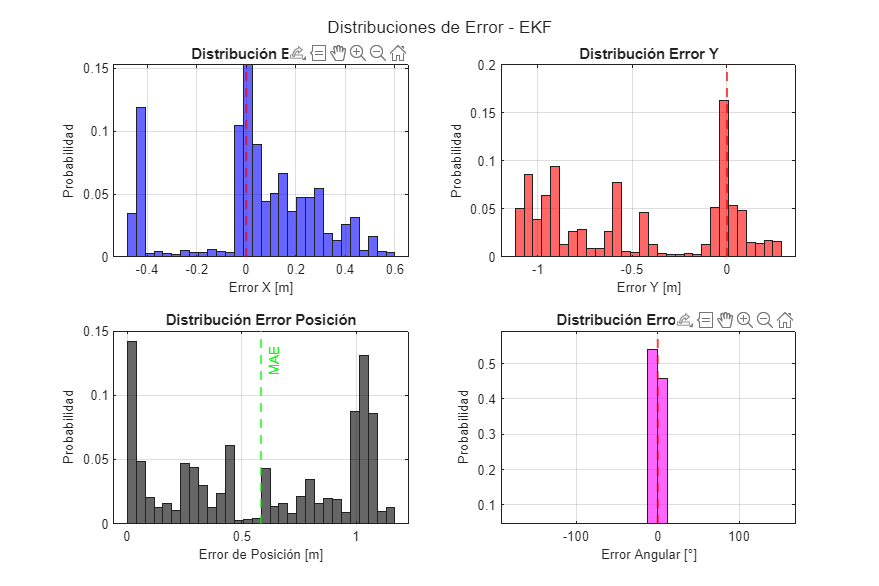

✓ Guardado: distribucion_errores_ekf.png


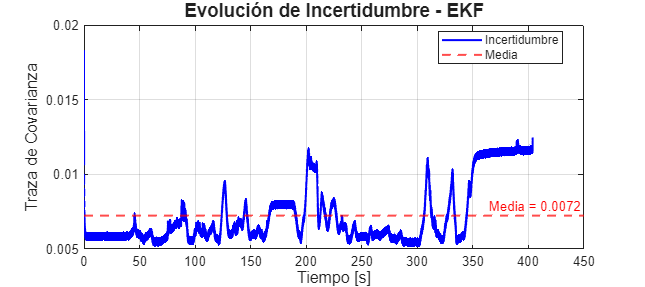

✓ Guardado: incertidumbre_ekf.png

✓ Todas las visualizaciones generadas


plot_results(metrics_ekf, vis_options);

fprintf('\n');

% Visualizar UKF
fprintf('Generando gráficas de UKF...\n');

Generando gráficas de UKF...


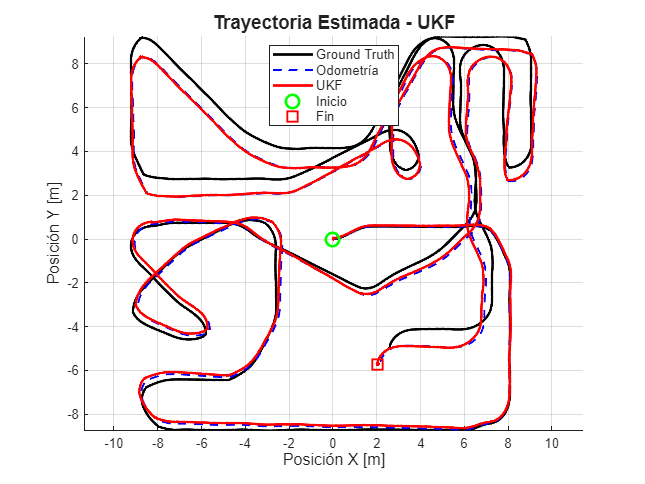

✓ Guardado: trayectoria_ukf.png


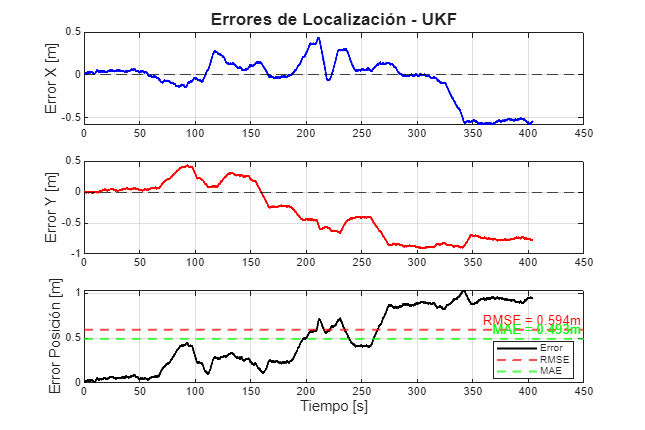

✓ Guardado: error_posicion_ukf.png


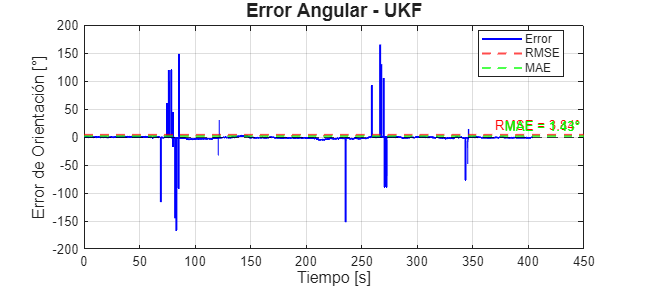

✓ Guardado: error_orientacion_ukf.png


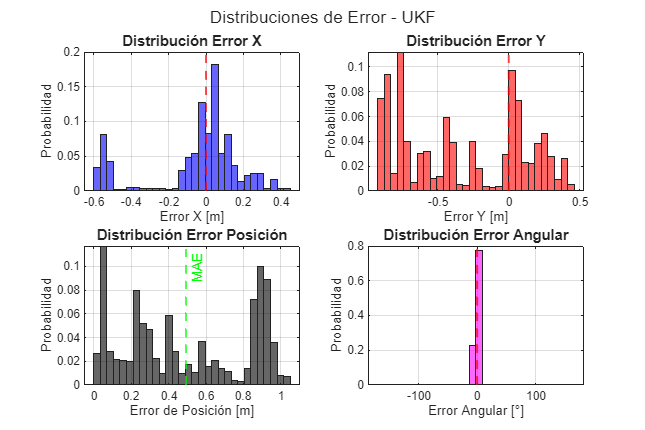

✓ Guardado: distribucion_errores_ukf.png


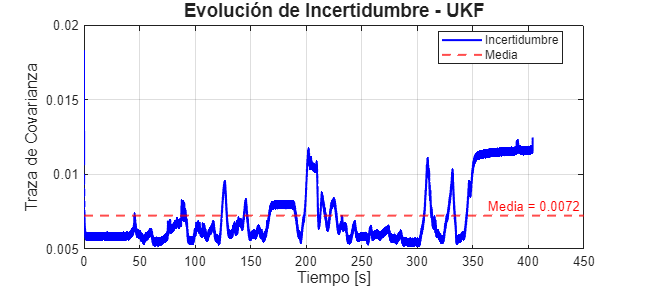

✓ Guardado: incertidumbre_ukf.png

✓ Todas las visualizaciones generadas


plot_results(metrics_ukf, vis_options);

fprintf('\n');

% Visualizar MCL
fprintf('Generando gráficas de MCL...\n');

Generando gráficas de MCL...


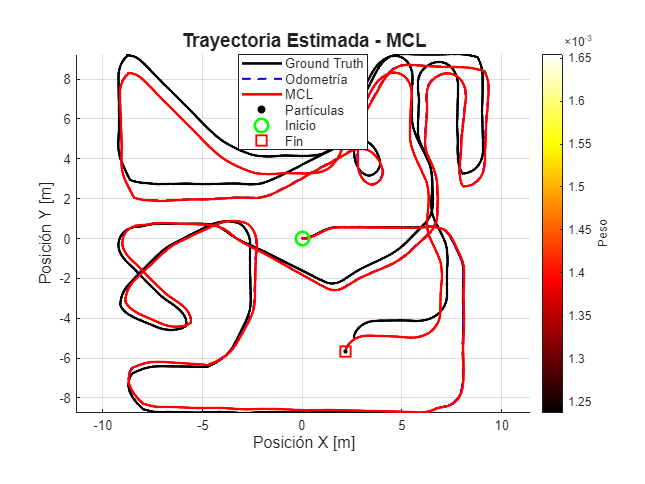

✓ Guardado: trayectoria_mcl.png


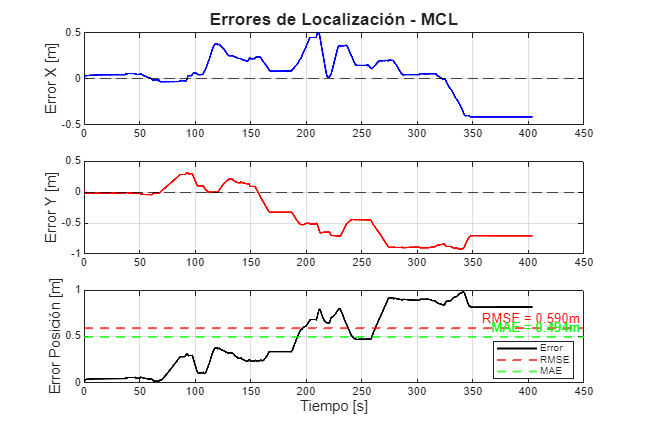

✓ Guardado: error_posicion_mcl.png


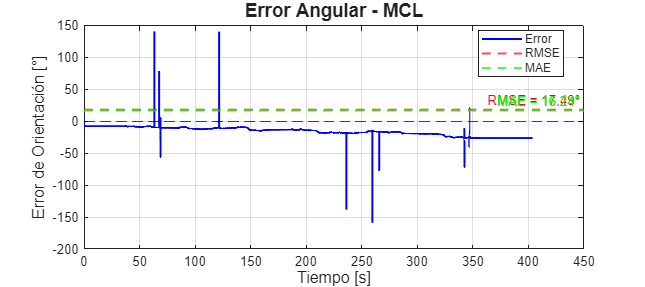

✓ Guardado: error_orientacion_mcl.png


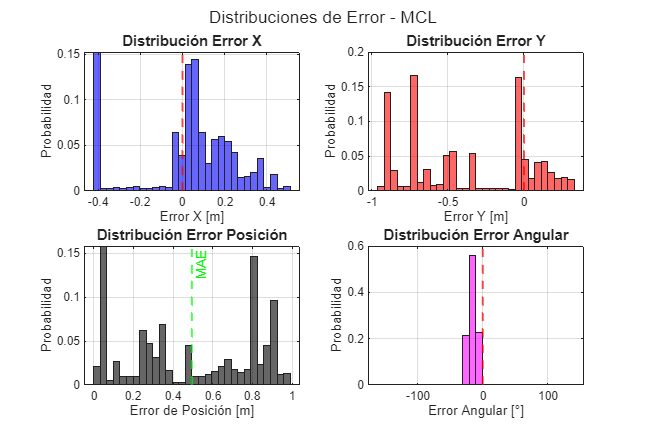

✓ Guardado: distribucion_errores_mcl.png


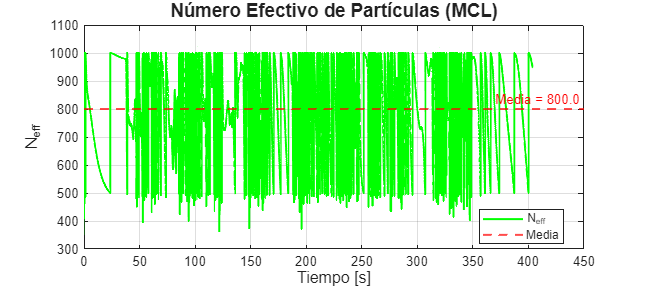

✓ Guardado: neff_mcl.png

✓ Todas las visualizaciones generadas


plot_results(metrics_mcl, vis_options);

fprintf('\n');

% Visualizar odometría
fprintf('Generando gráficas de Odometría...\n');

Generando gráficas de Odometría...


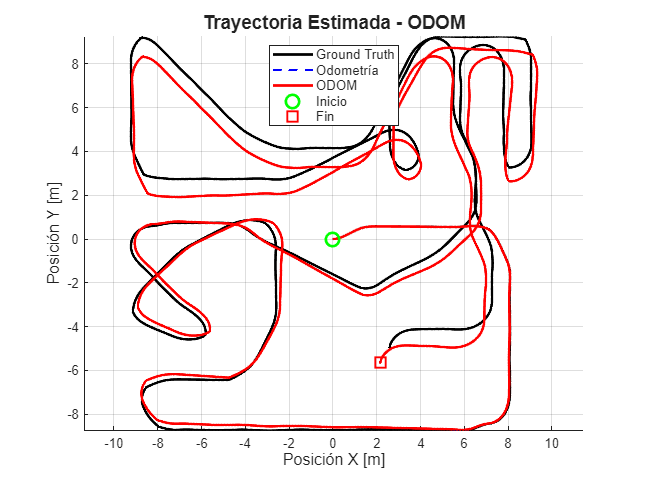

✓ Guardado: trayectoria_odom.png


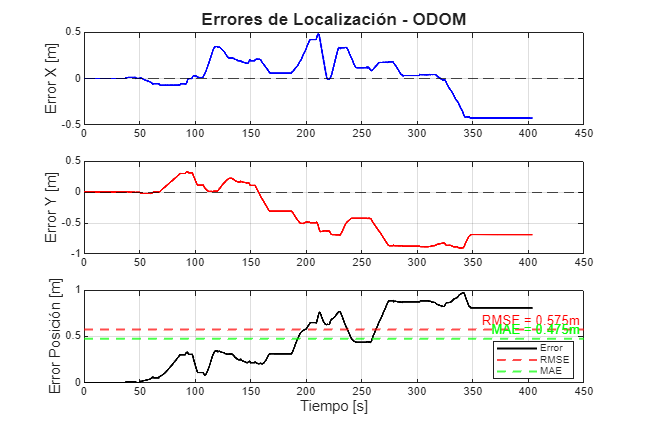

✓ Guardado: error_posicion_odom.png


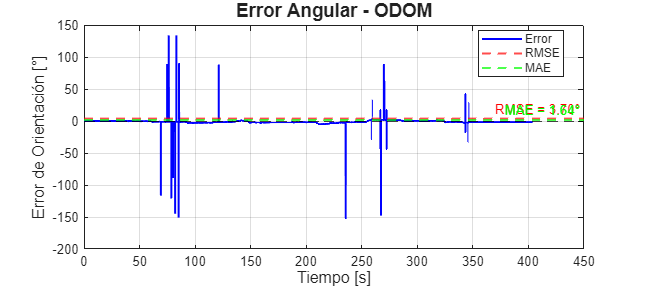

✓ Guardado: error_orientacion_odom.png


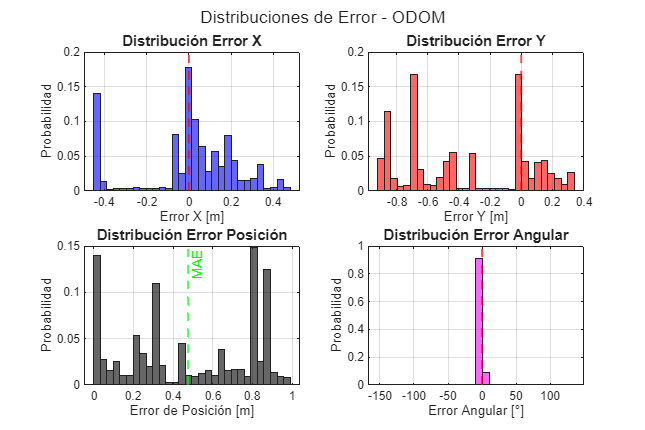

✓ Guardado: distribucion_errores_odom.png

✓ Todas las visualizaciones generadas


plot_results(metrics_odom, vis_options);

fprintf('\n');

if has_amcl
    fprintf('Generando gráficas de AMCL...\n');
    plot_results(metrics_amcl, vis_options);
    fprintf('\n');
end

fprintf('LAs gráficas han sido generadas\n\n');

LAs gráficas han sido generadas



Iniciamos la comparación entre los diferentes métiodos

=== COMPARACIÓN DE MÉTODOS DE LOCALIZACIÓN ===


>>> Evaluando método 1/4: EKF
=== EVALUACIÓN DE LOCALIZACIÓN ===
Método: EKF
Archivo: mir_basics_20251210_114529.bag

✓ Ground truth disponible

Ejecutando método de localización...
=== Iniciando EKF Localization ===
Cargando rosbag: mir_basics_20251210_114529.bag
Leyendo 16636 mensajes de odometría...
Leyendo 10003 mensajes de láser...

Ejecutando filtro EKF...
Progreso: 10% 20% 30% 40% 50% 60% 70% 80% 90% 100% 
✓ EKF completado
Estados estimados: 16636
Covarianza final: trace = 0.0125
✓ Localización completada

--- MÉTRICAS vs GROUND TRUTH ---
RMSE posición:    0.5670 m
RMSE orientación: 0.0660 rad (3.78°)
MAE posición:     0.4769 m
MAE orientación:  0.0277 rad (1.59°)
Error máx posición: 1.0213 m
Desv. std posición: 0.3066 m

Incertidumbre media: 0.0072

--- COMPARACIÓN CON ODOMETRÍA ---
RMSE odometría: 0.5749 m
Mejora:         1.4%

=== EVALUACIÓN COMPLETADA ===


>>> Evaluando método 2/4: UKF
=== EVALUACIÓN DE LOCALIZACIÓN ===
Métod

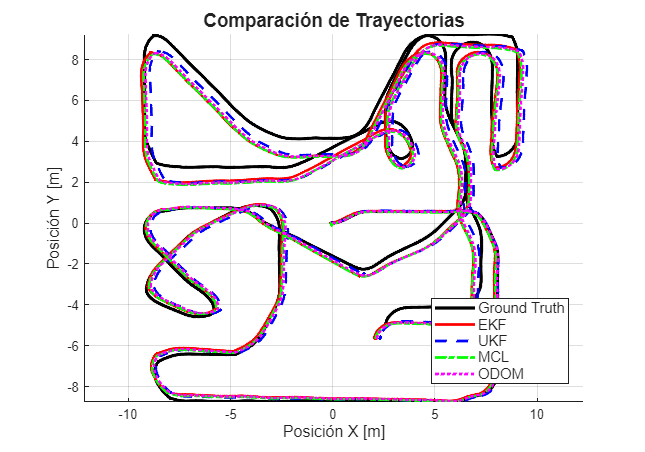


✓ Guardado: comparacion_trayectorias.png

=== TABLA COMPARATIVA DE MÉTRICAS ===

Método          |   RMSE [m] |    MAE [m] |    Max [m] |  RMSE θ[°] |   MAE θ[°]
-------------------------------------------------------------------------------------
EKF             |     0.5670 |     0.4769 |     1.0213 |       3.78 |       1.59
UKF             |     0.5604 |     0.4763 |     0.9260 |       4.64 |       1.85
MCL             |     0.6100 |     0.5098 |     1.0488 |      21.63 |      20.51
ODOM            |     0.5749 |     0.4753 |     0.9731 |       3.70 |       1.64



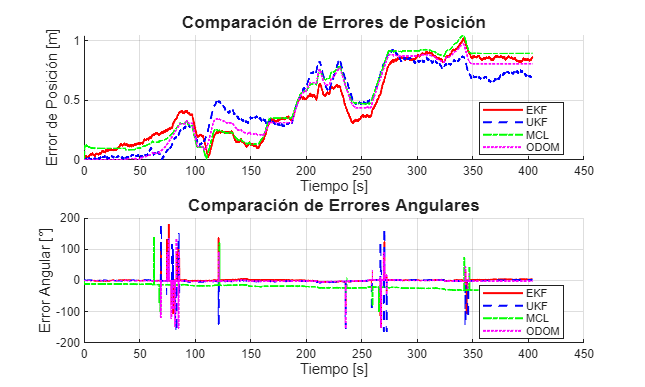

✓ Guardado: comparacion_errores.png


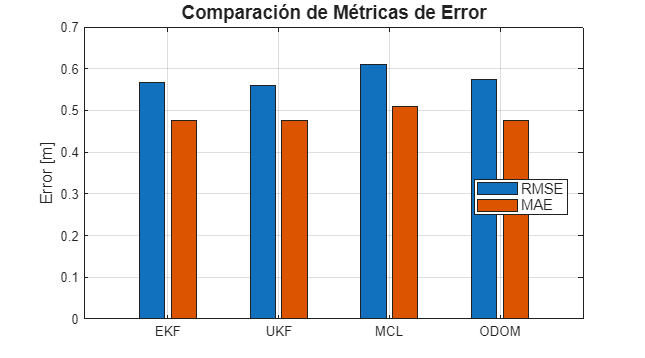

✓ Guardado: comparacion_metricas.png
✓ Guardado: metricas_comparativas.csv

=== COMPARACIÓN COMPLETADA ===



% Definimos los métodos a comparar
if has_amcl
    methods = {'ekf', 'ukf', 'mcl', 'amcl', 'odom'};
else
    methods = {'ekf', 'ukf', 'mcl', 'odom'};
end

% Configurar parámetros para comparación
params_comp = struct();
params_comp.ekf = params_ekf;
params_comp.ukf = params_ukf;
params_comp.mcl = params_mcl;

% Ejecutar comparación
compare_methods(bagFile, methods, params_comp);


fprintf('\nLa Comparación ha finalizado\n\n');


La Comparación ha finalizado



Generamos la tabla con los resultados

% Imprimimos la tabla resumen
fprintf('%-15s | %10s | %10s | %10s | %10s | %10s\n', ...
        'Método', 'RMSE [m]', 'MAE [m]', 'Max [m]', 'RMSE θ[°]', 'Mejora[%%]');

Método          |   RMSE [m] |    MAE [m] |    Max [m] |  RMSE θ[°] | Mejora[%%]


fprintf('%s\n', repmat('-', 1, 90));

------------------------------------------------------------------------------------------



% EKF
if isfield(metrics_ekf, 'rmse_pos')
    fprintf('%-15s | %10.4f | %10.4f | %10.4f | %10.2f | %10.1f\n', ...
            'EKF', metrics_ekf.rmse_pos, metrics_ekf.mae_pos, ...
            metrics_ekf.max_error_pos, rad2deg(metrics_ekf.rmse_yaw), ...
            metrics_ekf.improvement_vs_odom);
end

EKF             |     0.7085 |     0.5845 |     1.1660 |       4.89 |      -23.2



% UKF
if isfield(metrics_ukf, 'rmse_pos')
    fprintf('%-15s | %10.4f | %10.4f | %10.4f | %10.2f | %10.1f\n', ...
            'UKF', metrics_ukf.rmse_pos, metrics_ukf.mae_pos, ...
            metrics_ukf.max_error_pos, rad2deg(metrics_ukf.rmse_yaw), ...
            metrics_ukf.improvement_vs_odom);
end

UKF             |     0.5942 |     0.4929 |     1.0376 |       3.84 |       -3.4



% MCL
if isfield(metrics_mcl, 'rmse_pos')
    fprintf('%-15s | %10.4f | %10.4f | %10.4f | %10.2f | %10.1f\n', ...
            'MCL', metrics_mcl.rmse_pos, metrics_mcl.mae_pos, ...
            metrics_mcl.max_error_pos, rad2deg(metrics_mcl.rmse_yaw), ...
            metrics_mcl.improvement_vs_odom);
end

MCL             |     0.5902 |     0.4945 |     0.9805 |      17.49 |       -2.7



% AMCL
if has_amcl && isfield(metrics_amcl, 'rmse_pos')
    fprintf('%-15s | %10.4f | %10.4f | %10.4f | %10.2f | %10.1f\n', ...
            'AMCL', metrics_amcl.rmse_pos, metrics_amcl.mae_pos, ...
            metrics_amcl.max_error_pos, rad2deg(metrics_amcl.rmse_yaw), ...
            metrics_amcl.improvement_vs_odom);
end

% Odometría
if isfield(metrics_odom, 'rmse_pos')
    fprintf('%-15s | %10.4f | %10.4f | %10.4f | %10.2f | %10s\n', ...
            'Odometría', metrics_odom.rmse_pos, metrics_odom.mae_pos, ...
            metrics_odom.max_error_pos, rad2deg(metrics_odom.rmse_yaw), ...
            '-');
end

Odometría       |     0.5749 |     0.4753 |     0.9731 |       3.70 |          -



fprintf('\n');

Almacenamos la información en el Workspace

% Adicionamos las métricas en un archivo .mat
save('resultados/all_metrics.mat', 'metrics_ekf', 'metrics_ukf', 'metrics_mcl', 'metrics_odom');
fprintf('Métricas almacenadas en: resultados/all_metrics.mat\n');

Métricas almacenadas en: resultados/all_metrics.mat



% Creamos un archivo de texto con el resumen de las métricas
fid = fopen('resultados/resumen_resultados.txt', 'w');
fprintf(fid, 'PROYECTO INTEGRADOR: LOCALIZACIÓN DE ROBOTS\n');
fprintf(fid, 'Fecha: %s\n\n', datestr(now));
fprintf(fid, 'Archivo rosbag: %s\n\n', bagFile);
fprintf(fid, 'RESULTADOS:\n');
fprintf(fid, '%-15s | %10s | %10s | %10s | %10s\n', ...
        'Método', 'RMSE [m]', 'MAE [m]', 'Max [m]', 'RMSE θ[°]');
fprintf(fid, '%s\n', repmat('-', 1, 75));

if isfield(metrics_ekf, 'rmse_pos')
    fprintf(fid, '%-15s | %10.4f | %10.4f | %10.4f | %10.2f\n', ...
            'EKF', metrics_ekf.rmse_pos, metrics_ekf.mae_pos, ...
            metrics_ekf.max_error_pos, rad2deg(metrics_ekf.rmse_yaw));
end
if isfield(metrics_ukf, 'rmse_pos')
    fprintf(fid, '%-15s | %10.4f | %10.4f | %10.4f | %10.2f\n', ...
            'UKF', metrics_ukf.rmse_pos, metrics_ukf.mae_pos, ...
            metrics_ukf.max_error_pos, rad2deg(metrics_ukf.rmse_yaw));
end
if isfield(metrics_mcl, 'rmse_pos')
    fprintf(fid, '%-15s | %10.4f | %10.4f | %10.4f | %10.2f\n', ...
            'MCL', metrics_mcl.rmse_pos, metrics_mcl.mae_pos, ...
            metrics_mcl.max_error_pos, rad2deg(metrics_mcl.rmse_yaw));
end
if isfield(metrics_odom, 'rmse_pos')
    fprintf(fid, '%-15s | %10.4f | %10.4f | %10.4f | %10.2f\n', ...
            'Odometría', metrics_odom.rmse_pos, metrics_odom.mae_pos, ...
            metrics_odom.max_error_pos, rad2deg(metrics_odom.rmse_yaw));
end
fclose(fid);

fprintf('El resumen se ha guardado en: resultados/resumen_resultados.txt\n\n');

El resumen se ha guardado en: resultados/resumen_resultados.txt



Generamos la gráfica que consolida la información de todas ls trayectorias

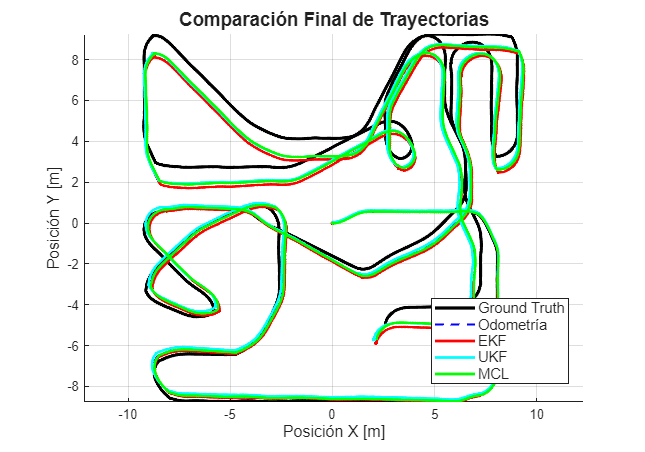

La gráfica del resumen la guardamos en: results/resumen_final.png



% Mostramos la gráfica con todas las trayectorias calculadas
if isfield(metrics_ekf, 'ground_truth')
    figure('Name', 'Resumen Final', 'Position', [100, 100, 1000, 700]);
    hold on; grid on; axis equal;
    
    gt = metrics_ekf.ground_truth;
    plot(gt.x, gt.y, 'k-', 'LineWidth', 2.5, 'DisplayName', 'Ground Truth');
    plot(metrics_odom.results.x, metrics_odom.results.y, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Odometría');
    plot(metrics_ekf.results.x, metrics_ekf.results.y, 'r-', 'LineWidth', 2, 'DisplayName', 'EKF');
    plot(metrics_ukf.results.x, metrics_ukf.results.y, 'c-', 'LineWidth', 2, 'DisplayName', 'UKF');
    plot(metrics_mcl.results.x, metrics_mcl.results.y, 'g-', 'LineWidth', 2, 'DisplayName', 'MCL');
    
    if has_amcl
        plot(metrics_amcl.results.x, metrics_amcl.results.y, 'm-', 'LineWidth', 2, 'DisplayName', 'AMCL');
    end
    
    xlabel('Posición X [m]', 'FontSize', 12);
    ylabel('Posición Y [m]', 'FontSize', 12);
    title('Comparación Final de Trayectorias', 'FontSize', 14, 'FontWeight', 'bold');
    legend('Location', 'best', 'FontSize', 11);
    hold off;
    
    saveas(gcf, 'resultados/resumen_final.png');
    fprintf('La gráfica del resumen la guardamos en: results/resumen_final.png\n\n');
end